# Earth Rotation Demonstration

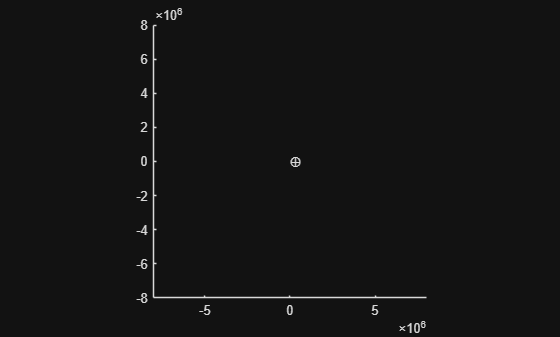

clearvars
clf;
h2f = figure(1);
h2a = axes(h2f);
plotLim = 8000000;
h2a.XLim = [-plotLim +plotLim];
h2a.YLim = [-plotLim +plotLim];
text(h2a, 0, 0, 0, EARTH.SYMBOL);
%text(h2a,+EARTH.RADIUS+1e3,0,0,EARTH.ARIES);
axis(h2a,'square');


% Spring 2025 is March     20
% Summer 2025 is June      20
% Fall   2025 is September 22
% Winter 2025 is December  21

fallJD = EARTH.calendarToJulianDay(2025,  9, 22, 0, 0, 0);
fallJD = fallJD - .00216316405;

[x1, y1, z1] = EARTH.LLA2ECI(fallJD + 0/86400, 0, 0, 0);

Unrecognized function or variable 'xyzYawRad'.

Error in EARTH.LLA2ECI (line 131)
      [x,y,z] = xyzYawRad(x, y, z, EARTH.phiGrn(JD));
      ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

[x2, y2, z2] = EARTH.LLA2ECI(fallJD + 1/86400, 0, 0, 0);
V0 = [x2, y2, z2] - [x1, y1, z1];

for ii = 1:300:(86400/8)
   inc = ii/86400;
   [x, y, z] = EARTH.LLA2ECI(fallJD+inc, 0, 0, 0);
   plot3(h2a, x, y, z, "*", "Color", "#964B00");

   x = x1 + V0(1)*ii;
   y = y1 + V0(2)*ii;
   z = z1 + V0(3)*ii;
   plot3(h2a, x, y, z, ".", 'Color','blue');
end

grid
title(h2a,"ECI point on Earth")
subtitle(h2a,"ECI point on tangent")